# The role of poles in the dynamics of the system

## What if we push the poles too close to the unit circle?

Let us define a Butterworth filter and increase the order. The transfer form the analogue to the digital domain by the bilinear transform will introduce numerical errors. How far we we push that?

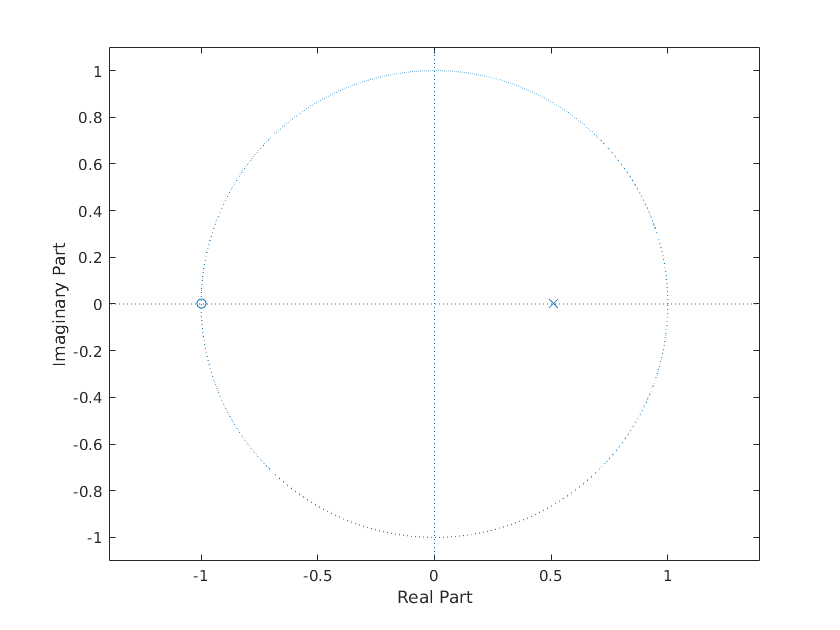

% filter parameters
fs = 10000;    % sampling frequency
n = 1;         % filter order
fc = 1000;     % cutoff frequency

wc = fc/(fs/2);    % normalized cutoff frequency

% design the filter
[B, A] = butter(n, wc);
figure('name','Pole-zero diagram')
zplane(B, A);

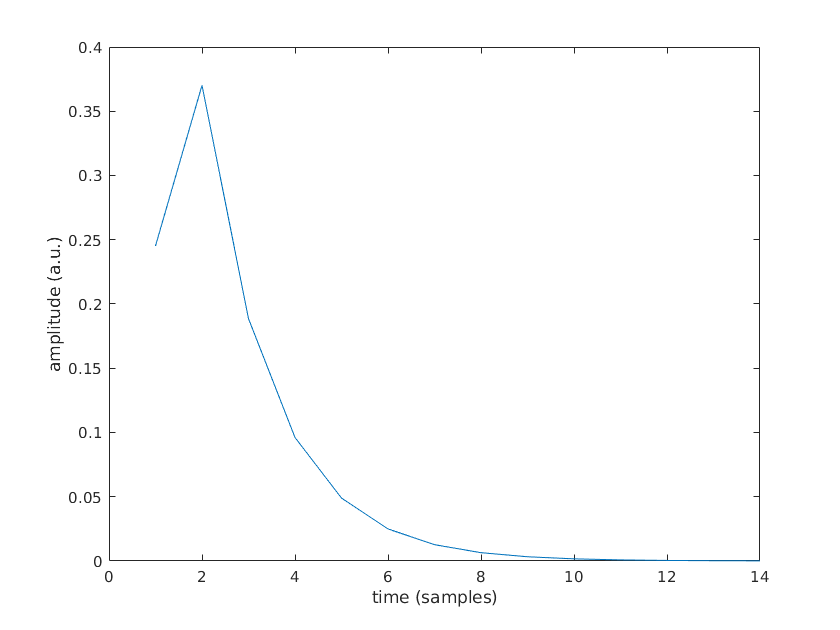

ir_butter = impz(B, A);

% plotting
plot(ir_butter)
xlabel('time (samples)')
ylabel('amplitude (a.u.)')